# Rock vs No Rock: Data recording sheet

Author: Ross Wilkinson

University: University of Colorado Boulder

## Testing information

- Experiment: Rock vs No Rock

- Objective: Test effect of bicycle lean on maximal power output 

- Date: September 16, 2020

- Location: Locomotion Laboratory

- Subject: UC

- Quarq calibration factor: 323

## Experimental setup

### Protocol reminders

- Charge Garmin, iPad, and IMUs

- Clarify participant understanding and answer questions

- Set saddle height and handlebar position

- Sanitize bicycle

- Calibrate power meter

- Setup cooling fan

- Gift card and signature

### Experimental conditions

- Preferred Lean

- Self-restricted

- Locked

### Trial order

- Warm up: 5 min at ~100 W (3.5 lb)

- Familiarization: Standing and leaning (8.5 lb)

- Pmax Test: 3 x hanging weights under condition 1

- Block 1: Randomize

- Block 2: Randomize

- Block 3: Randomize

### Environmental conditions

- Temperature (C): 21.1

- Humidity (%): 39.1 

- Pressure (mmHg): 636            

- Altitude (m): 1641

### Subject characteristics

Record subject characteristics to table for group data analysis.

number = 12;
code = {'UC'};
sex = {'F'};
age = 28;
mass = 200; %lb
height = 1.68; %m

T = table(number,code,sex,age,mass,height)

T = 1×6 table
    number     code      sex     age    mass    height
    ______    ______    _____    ___    ____    ______

      11      {'UC'}    {'F'}    28     200      1.68 


## Results

Use mass to calculate individualised hanging weights for Pmax Test.

listPerc = [0.04; 0.06; 0.08];
listHang = listPerc * mass

listHang =      8
    12
    16


### Pmax test

Record Pmax test results. Fit curve to predict optimal hanging weight.

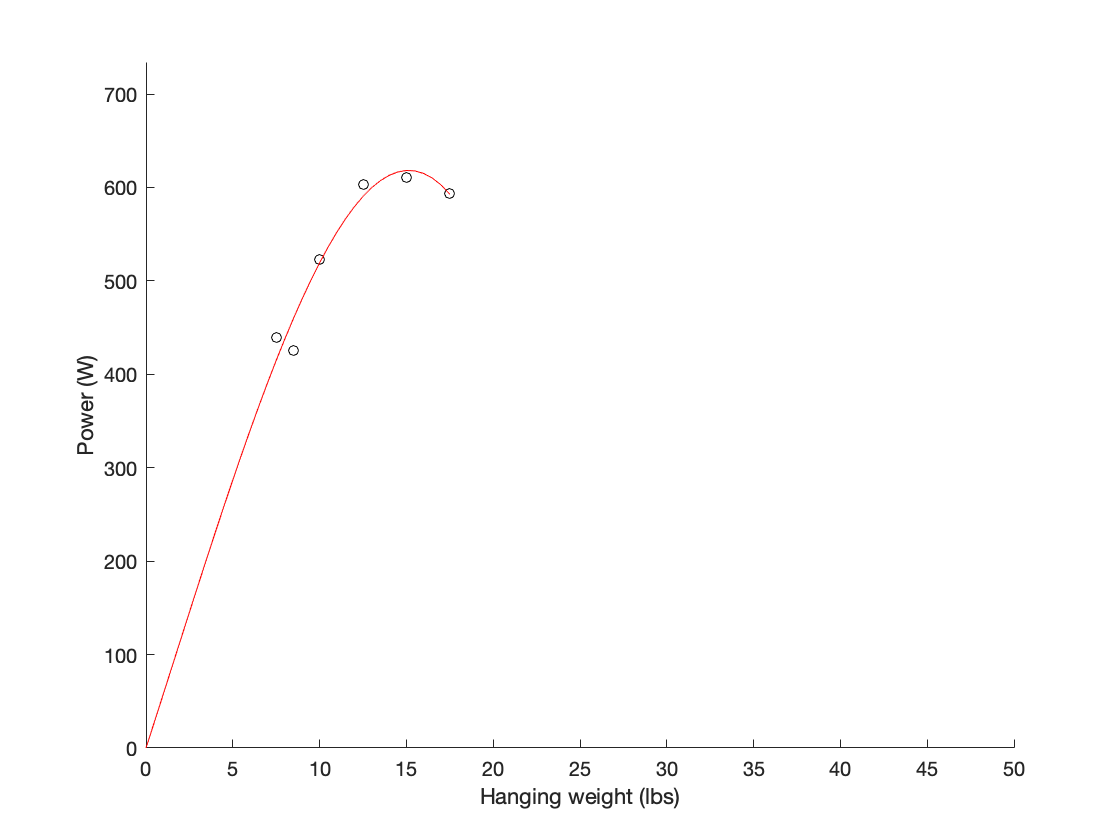

x = [8.5; 7.5; 10; 12.5; 15; 17.5]; % hanging weight
x_ = [106; 115; 108; 102; 93; 77]; % cadence
y = [426; 439; 523; 603; 611; 594]; % power output

% fit curve: power vs hang
[c, ~, ~] = fit(x,y,'poly3','Lower',[-Inf -Inf -Inf 0],'Upper',[Inf Inf Inf 0]);
% [c, ~, ~] = fit(x,y,'poly2');

new_x = 0:max(x)/(max(x)*2):max(x);
new_y = c.p1*new_x.^3 + c.p2*new_x.^2 + c.p3*new_x + c.p4;

% plot curve
scatter(x,y,25,'k','filled');
hold on
plot(new_x,new_y,'k-')

% edit figure
box off
xlabel('Hanging weight (lbs)')
ylabel('Power (W)')
xlim([0 50])
ylim([0 max(y)*1.2])


% find optimal x and y
[yOpt,I] = max(new_y);
xOpt = new_x(I);

fprintf('Predicted maximal power output = %4.2f Watts \n', yOpt)

Predicted maximal power output = 618.18 Watts 


fprintf('Predicted optimal hanging weight = %4.2f Lbs \n', xOpt)

Predicted optimal hanging weight = 15.00 Lbs 


### Randomize trial order within each block

randperm(3)

ans =      2     3     1


randperm(3)

ans =      3     1     2


randperm(3)

ans =      2     1     3


### Experimental results

Record results to array then convert to table.

data = [
    12, 2, 1, 15, 626, 94;
    12, 3, 1, 15, 744, 108;
    12, 1, 1, 15, 672, 100;
    12, 3, 2, 15, 717, 110;
    12, 1, 2, 15, 662, 101;
    12, 2, 2, 15, 679, 102;
    12, 2, 3, 15, 692, 105;
    12, 1, 3, 15, 699, 105;
    12, 3, 3, 15, 692, 108;
    ];

T_ = array2table(data, ...
    'VariableNames',{'subject','condition','trial','hangingWeight','power','cadence'})

T_ = 9×6 table
    subject    condition    trial    hangingWeight    power    cadence
    _______    _________    _____    _____________    _____    _______

      11           2          1           15           626        94  
      11           3          1           15           744       108  
      11           1          1           15           672       100  
      11           3          2           15           717       110  
      11           1          2           15           662       101  
      11           2          2           15           679       102  
      11           2          3           15           692       105  
      11           1          3           15           699       105  
      11           3          3           15           692       108  

## Data analysis

Calculate mean and SD power and cadence for experimental trials.

varfun(@mean,T_,'InputVariables',{'power','cadence'}, ...
    'GroupingVariables',{'condition'})

ans = 3×4 table
    condition    GroupCount    mean_power    mean_cadence
    _________    __________    __________    ____________

        1            3           677.67            102   
        2            3           665.67         100.33   
        3            3           717.67         108.67   


varfun(@std,T_,'InputVariables',{'power','cadence'}, ...
    'GroupingVariables',{'condition'})

ans = 3×4 table
    condition    GroupCount    std_power    std_cadence
    _________    __________    _________    ___________

        1            3           19.14        2.6458   
        2            3          34.962        5.6862   
        3            3          26.006        1.1547   
